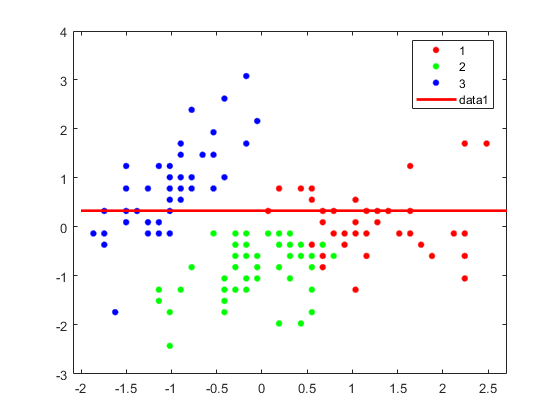

% Load the Iris dataset
load fisheriris

% Extract the features and true labels
X = meas;
X = zscore(X);

true_labels = grp2idx(species);  % true class labels (N x 1)
percentageCell = {'Number of Clusters' 'Accuracy'};
% K = number of clsuters
K = 3;
while K <= 100 %increment the number of clusters
% pick K number of random points
centroids = X(randperm(size(X, 1), K), :);

% max iterations
max_iters = 100;


% init labels
labels = zeros(size(X, 1), 1);


% k mean algo 
for iter = 1:max_iters
    % assign each point to closest cluster
    distances = pdist2(X,centroids);
    [~,labels] = min(distances,[],2);
    
    %update centroids
    for k = 1:K
        centroids(k,:) = mean(X(labels==k,:),1);
    end
    
 
    
end

% Compute accuracy
acc = 0;
for k = 1:K
    idx = (labels == k);
    
    modes = mode(true_labels(idx));
    correct = sum(true_labels(idx) == modes);
    acc = acc + correct;
end

% compute mean percentage of elements in each cluster
percentages = zeros(K, 1);
for k = 1:K
    percentages(k) = sum(labels == k) / length(labels);
end

accuracy = acc/length(labels);
percentageCell{end+1, 1} = K;
percentageCell{end,2} = accuracy;
mean_percentage = mean(percentages);
figure(K)
gscatter(X(:,1),X(:,2),labels)
line([-2 3], [mean_percentage mean_percentage], 'Color', 'red', 'LineWidth', 2);
K = K + 1;
end